clc; clear; close all;

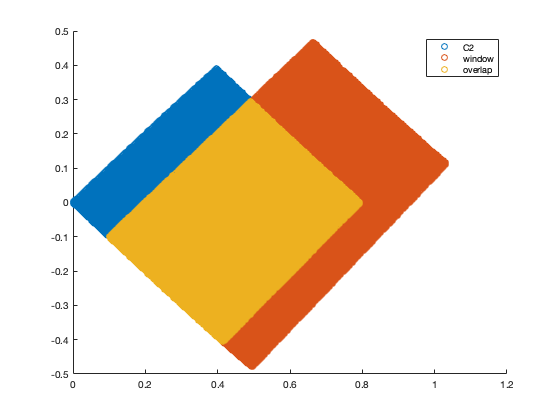

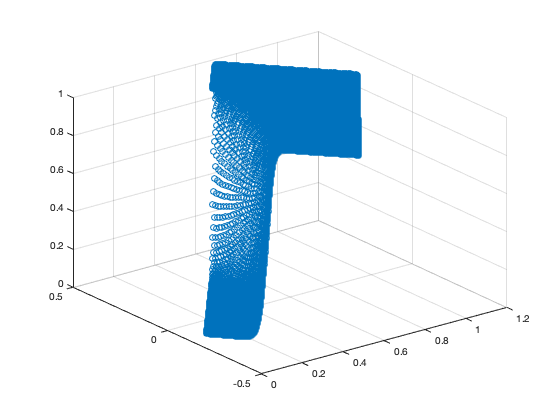

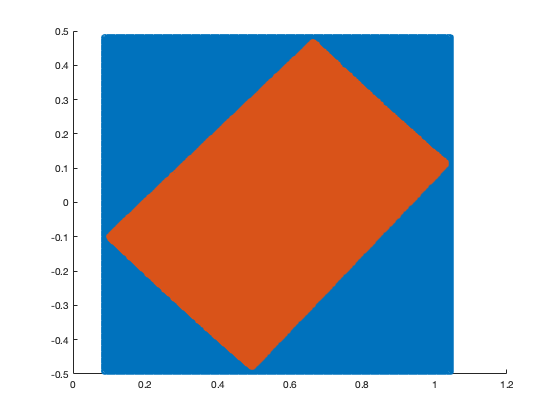

start first pass
construct nan map


xi_exact =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


%%% Set up
f = @(x, y) ones(size(x));

l_theta = @(theta) [2*sin(theta/2), -sin(theta)];

d = 1;

for scale_factor = 2
    h_R = 0.01 *(1/2)^scale_factor;
    
    n_C2 = round(0.8/(h_R*2));
    n_S_h = round(0.4/h_R);
    h_S = h_R;
    
    C2_patch = construct_C2_patch_old(f, 0.4, 2*pi-0.4, 0, n_C2, n_C2); % data associated with patch
    window_patch_xi = construct_S_patch(f, 0.1, 0.5, h_S, n_S_h, 2*n_C2);
    window_patch_eta = construct_S_patch(f, 2*pi-0.1, 2*pi-0.5, h_S, n_S_h, 2*n_C2);
    
    [C2_norm, xi_norm, eta_norm] = C2_patch.compute_phi_normalization(window_patch_xi, window_patch_eta);
%     
%     [XI, ETA] = C2_patch.xi_eta_mesh;
%     C2_patch.f_XY = C2_patch.phi(XI, ETA) ./ C2_norm;
    
    [XI_xi, ETA_xi] = window_patch_xi.xi_eta_mesh;
    window_patch_xi.f_XY = window_patch_xi.phi(XI_xi, ETA_xi) ./ xi_norm;
    
    figure;
    [X, Y] = window_patch_xi.xy_mesh();
    scatter3(X(:), Y(:), window_patch_xi.f_XY(:))
    
    R_x_bounds = [window_patch_xi.x_min-5*h_R, window_patch_xi.x_max+5*h_R];
    R_y_bounds = [window_patch_xi.y_min-5*h_R, window_patch_xi.y_max+5*h_R];
    
    [boundary_X, boundary_Y] = window_patch_xi.boundary_mesh_xy;
    
    R = R_cartesian_mesh_obj(R_x_bounds(1), R_x_bounds(2), R_y_bounds(1), R_y_bounds(2), h_R, boundary_X, boundary_Y);
    figure;
    scatter(R.R_X(:), R.R_Y(:));
    hold on;
    scatter(X(:), Y(:))
    [P, R_patch_idxs] = R.interpolate_patch(window_patch_xi, d+3, false);
    
    xi_exact = zeros(size(R_patch_idxs))
    for i = 1:length(R_patch_idxs)
        xi_eta_point = P(R_patch_idxs(i));
        xi_phi_point = window_patch_xi.phi(xi_eta_point(1), xi_eta_point(2));
        

        [C2_xi, C2_eta] = C2_patch.inverse_M_p(R.R_X(R_patch_idxs(i)), R.R_Y(R_patch_idxs(i)), nan);
        C2_phi_point = C2_patch.phi(C2_xi, C2_eta);
        
        xi_exact(i) = xi_phi_point/(C2_phi_point + xi_phi_point);
    end
end

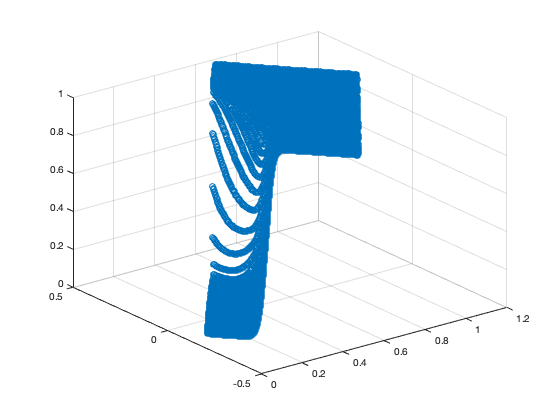


figure;
scatter3(R.R_X(R_patch_idxs), R.R_Y(R_patch_idxs), xi_exact)

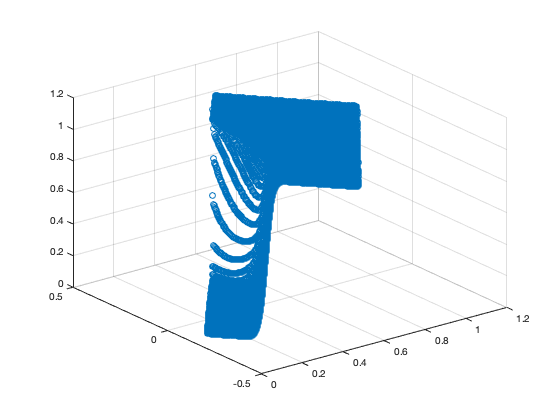


figure;
scatter3(R.R_X(R_patch_idxs), R.R_Y(R_patch_idxs), R.f_R(R_patch_idxs))

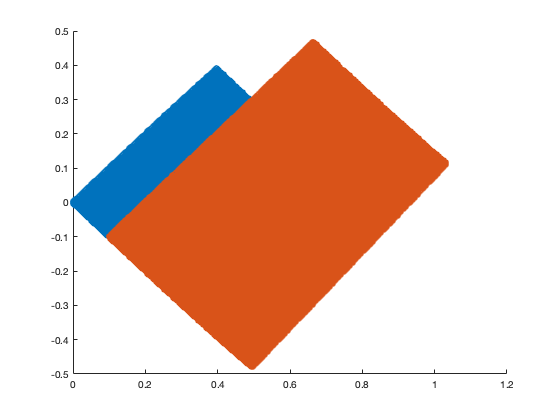

figure;
[X, Y] = C2_patch.xy_mesh;
scatter(X(:), Y(:));
hold on;
[X, Y] = window_patch_xi.xy_mesh;
scatter(X(:), Y(:))

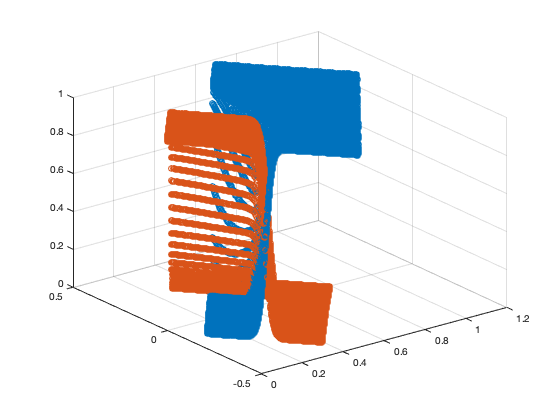


figure;
scatter3(R.R_X(R_patch_idxs), R.R_Y(R_patch_idxs), xi_exact)
hold on;
[X, Y] = C2_patch.xy_mesh;
[XI, ETA] = C2_patch.xi_eta_mesh;
scatter3(X(:), Y(:), C2_patch.phi(XI(:), ETA(:))./C2_norm(:))

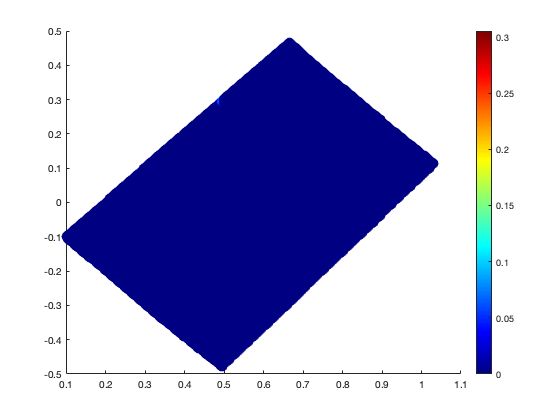


figure;
scatter(R.R_X(R_patch_idxs), R.R_Y(R_patch_idxs), 100, abs(R.f_R(R_patch_idxs) - xi_exact), 'filled');

% Add a color bar
colorbar;

% Set colormap
colormap(jet);

function C2_patch = construct_C2_patch_old(f, theta_A, theta_B, theta_C, n_xi, n_eta)
    l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
    
    l_A = @(xi) xi*(theta_A - theta_C) + theta_C;
    l_B = @(eta) eta*(theta_B - theta_C - 2*pi) + theta_C + 2*pi; % account for wrap around
    
    M_p = @(xi, eta) l_theta(l_A(xi)) + l_theta(l_B(eta)) - l_theta(theta_C);
    J = @(v) [theta_A*cos(v(1)*theta_A/2) (theta_B-2*pi)*cos((v(2)*(theta_B-2*pi)+2*pi)/2); -theta_A*cos(v(1)*theta_A) -(theta_B-2*pi)*cos(v(2)*(theta_B-2*pi)+2*pi)];
    
    xi_mesh = linspace(0, 1, n_xi+1);
    eta_mesh = linspace(0, 1, n_eta+1);
    
    [XI, ETA] = meshgrid(xi_mesh, eta_mesh);
    XY = M_p(XI(:), ETA(:));
    
    f_XY = reshape(f(XY(:, 1), XY(:, 2)), [n_eta+1, n_xi+1]);
    
    C2_patch = C2_patch_old_obj(M_p, J, n_xi, n_eta, 0, 1, 0, 1, f_XY, nan); % data associated with patch
end

function C2_patch = construct_C2_patch(f, theta_A, theta_B, theta_C, n_xi, n_eta)
    l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
    
    l_A = @(xi) xi*(theta_A - theta_C) + theta_C;
    l_B = @(eta) eta*(theta_B - theta_C - 2*pi) + theta_C + 2*pi; % account for wrap around
    
    M_p = @(xi, eta) l_theta(l_A(xi)) + l_theta(l_B(eta)) - l_theta(theta_C);
    J = @(v) [theta_A*cos(v(1)*theta_A/2) (theta_B-2*pi)*cos((v(2)*(theta_B-2*pi)+2*pi)/2); -theta_A*cos(v(1)*theta_A) -(theta_B-2*pi)*cos(v(2)*(theta_B-2*pi)+2*pi)];
    
    xi_mesh = linspace(0, 1, n_xi+1);
    eta_mesh = linspace(0, 1, n_eta+1);
    
    [XI, ETA] = meshgrid(xi_mesh, eta_mesh);
    XY = M_p(XI(:), ETA(:));
    
    f_XY = reshape(f(XY(:, 1), XY(:, 2)), [n_eta+1, n_xi+1]);
    
    C2_patch = C2_patch_obj(M_p, J, n_xi, n_eta, 0, 1, 0, 1, f_XY, nan); % data associated with patch
end

function S_patch = construct_S_patch(f, theta_A, theta_B, h, n_xi, n_eta)
    l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
    
    l_A = @(xi) (theta_B - theta_A)*xi + theta_A;
    nu = @(xi) [cos(l_A(xi)), cos(l_A(xi)/2)] ./ sqrt(cos(l_A(xi)).^2 + cos(l_A(xi)/2).^2);
    
    M_p_general = @(xi, eta, H) l_theta(l_A(xi)) + eta.*H.*nu(xi);%./nu_norm(xi);
    % H is a function of h and n_eta
    
    theta_diff = theta_B - theta_A;
    J = @(v, H) [theta_diff*cos(l_A(v(1))/2)-v(2)*H*theta_diff*sin(l_A(v(1))), H*cos(l_A(v(1))); -1*theta_diff*cos(l_A(v(1)))-v(2)*H*theta_diff/2*sin(l_A(v(1))/2), H*cos(l_A(v(1))/2)];
    
    xi_mesh = linspace(0, 1, n_xi+1);
    eta_mesh = linspace(0, 1, n_eta+1);
    
    [XI, ETA] = meshgrid(xi_mesh, eta_mesh);
    XY = M_p_general(XI(:), ETA(:), h*n_eta);
    
    f_XY = reshape(f(XY(:, 1), XY(:, 2)), [n_eta+1, n_xi+1]);
    
    S_patch = S_patch_obj(M_p_general, J, n_xi, n_eta, 0, 1, 0, 1, f_XY, h, nan);
end